# Karhunen–Loève transform

## Optimum orthogonal transforms

KLT transform is a $p\times p$ orthogonal transform for random signals. It is also known as PCA.

The forward transform can be expressed as

        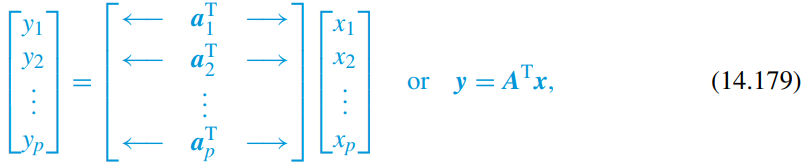

where $A$ is a $p\times p$ transform matrix.

To simplify the computation of the inverse transform, we require that the matrix ***A ***is orthogonal so:

        
$$A^T =A^{-1}$$


The inverse transform provides an expansion of the input signal vector ***x ***into orthogonal components using as a basis the columns of transform matrix ***A***.  

**The Karhunen–Loève transform **We wish to find the orthogonal transform that provides a representation of the input signal vector which is optimum with respect to the mse criterion. 

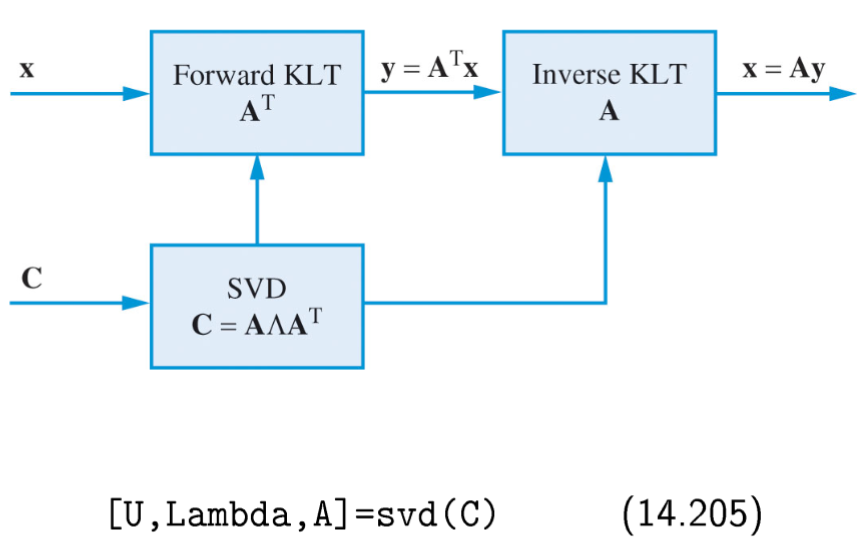

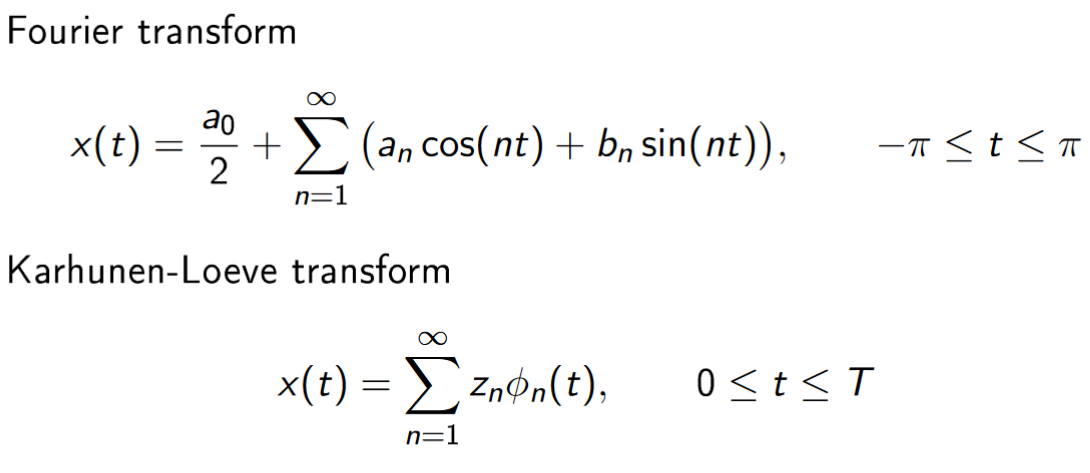

## Quiz: What happens if we perform a KLT on a white noise process?

clear variables;

C = cov(randn(100,10));
[U, lambda, A] = svd(C);
diag(lambda)'

ans =     1.4367    1.3516    1.2134    0.9697    0.9281    0.7613    0.7375    0.6649    0.6179    0.4922


X = randn(100,4);
C = cov(X - mean(X));
[U, lambda, A] = svd(C);
diag(lambda)'

ans =     1.2396    0.9595    0.8549    0.7867


## Karhunen–Loève Transform Implementation

clear variables;

Consider the following piece of Matlab code: 

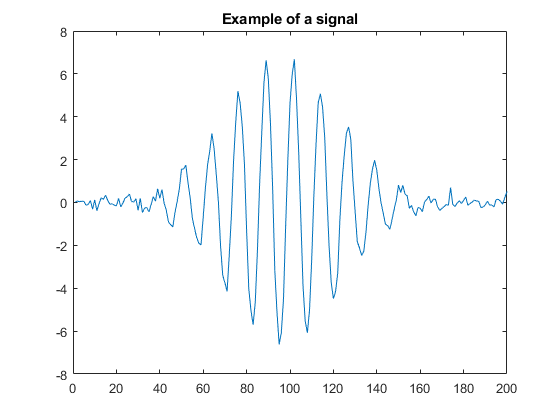

%% Settings
n=200; % segment length

t=0:n-1; % time axis (a column vector 1xn)
t=t(:);  % time axis (as row vector nx1)

amplitudeNoise=10; % noise parameters
sigmaNoise=20;
t0Noise=20;
whiteNoise=0.2;

A=5+amplitudeNoise*rand(1);
sigma=10+sigmaNoise*rand(1);
t0=100+t0Noise*randn(1);
s=A*exp( -(t-t0).^2 / (2*sigma^2)).*cos(0.5*t);
s=s+whiteNoise*randn(n,1);
plot(s);
title('Example of a signal')


N=10; % Number of signals to generate
X=zeros(n,N);

%% build up an 'observed' data set
for q=1:N
    A=5+amplitudeNoise*rand(1);  % The highest peak
    sigma=10+sigmaNoise*rand(1); % The "width" of pulse
    t0=100+t0Noise*randn(1);     % The center of the highest peak
    s=A*exp( -(t-t0).^2 / (2*sigma^2)).*cos(0.5*t);
    X(:,q)=s+whiteNoise*randn(n,1);
end

rankX = rank(X)

rankX = 10

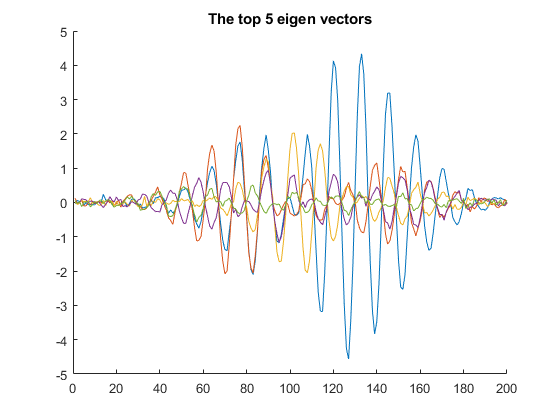


%% Calculate C using 14.206 and perform a KLT
C=zeros(n,n);
mean_vector = mean(X, 2); % Compute mean vector across all samples.
for q=1:N
    % x=X(:,q)-mean(X(:,q));  % Original code, seems wrong?
    x = X(:,q) - mean_vector; % My code
    C = C + x*x';
end
C=C/N;
[U, lambda, A]=svd(C);

%% Plot results
figure(1)
clf(figure(1))
hold on
for q=1:5
  plot(A(:,q)*sqrt(lambda(q,q)))
end
title('The top 5 eigen vectors')
hold off

figure(2)
stem(diag(lambda))
xlabel('Component')
ylabel('Eigenvalue')


## Work through the code and explain what it does.

## Play around with the noise parameters and comment on how the plots are altered by the noise parameters.  

When the noise parameters are all set to zero, we are generating the same signal duplicated N times. So our $\mathit{\mathbf{X}}$ has $N$ columns of the same $n\times 1$vector. This means the rank of the matrix is 1. 

Changing the amplitutde noise parameter does not effect the rank of the matrix since changes in amplitude cause vectors to be scaled.

Changes in the other noise parameters causes the $X$ matrix to be full rank (almost at every generation) since the signals are more likely to be shifted.

## How are the results affected by N, the number of experiments?  

When N=5

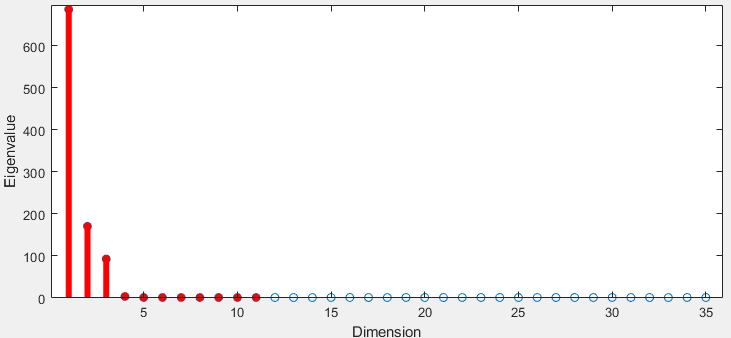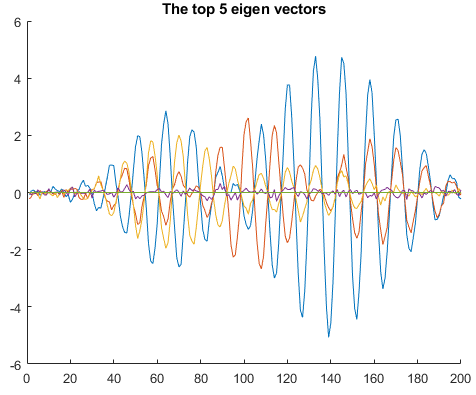

When N=10

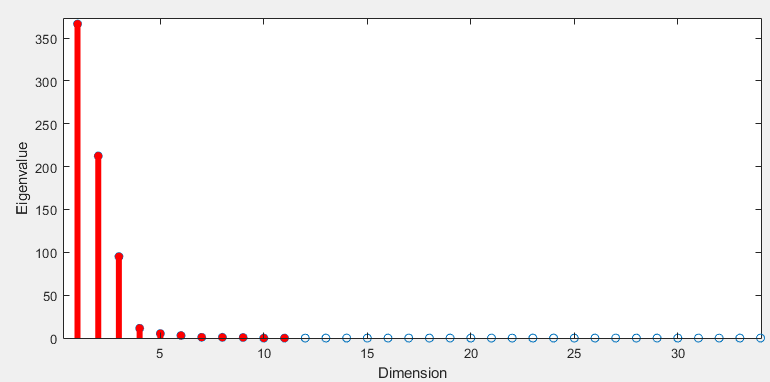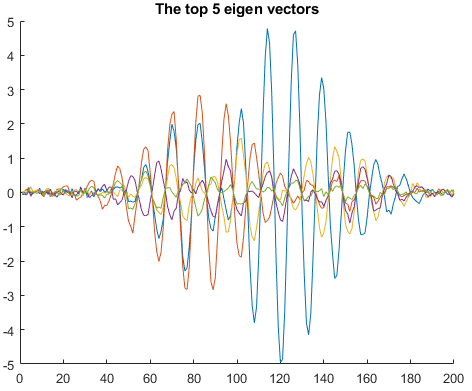

When N=100

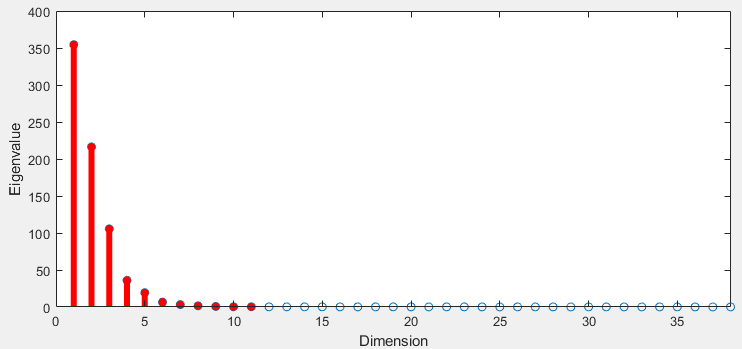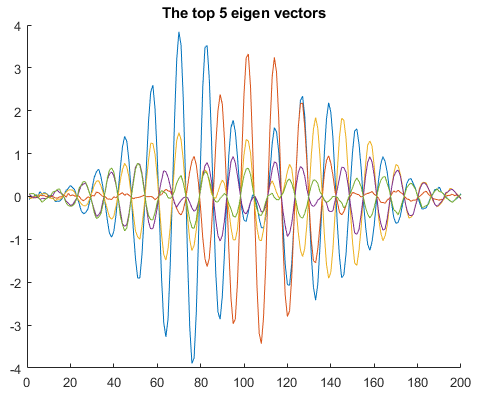

N=1000

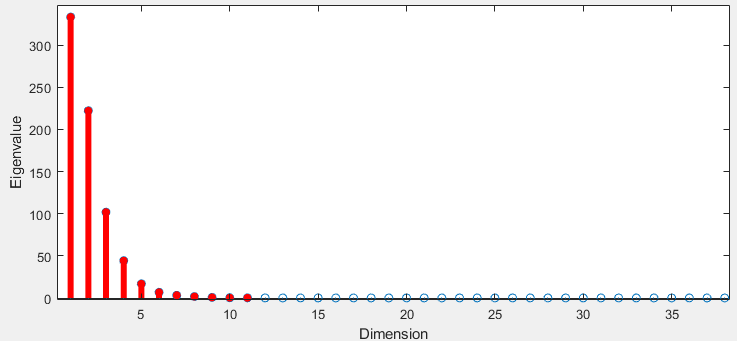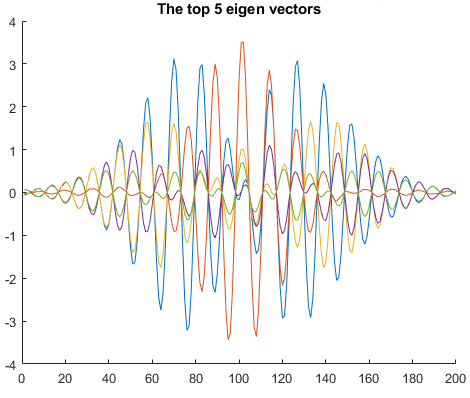

## What happens if colored noise is used instead of white noise?  

Even with coloured noise, it seems that the largest variance within the different signals can be explained by the top 5-10 components.

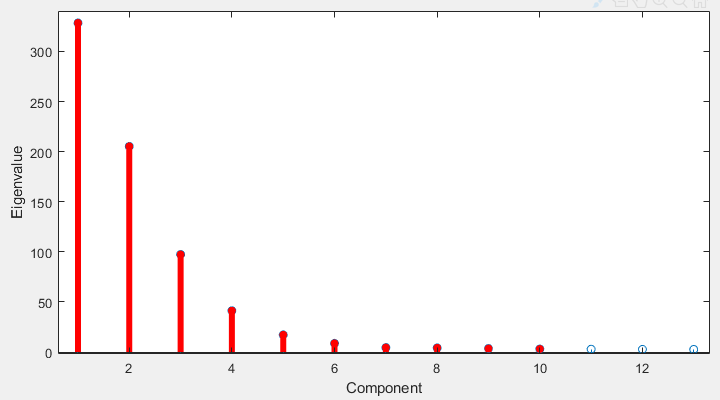

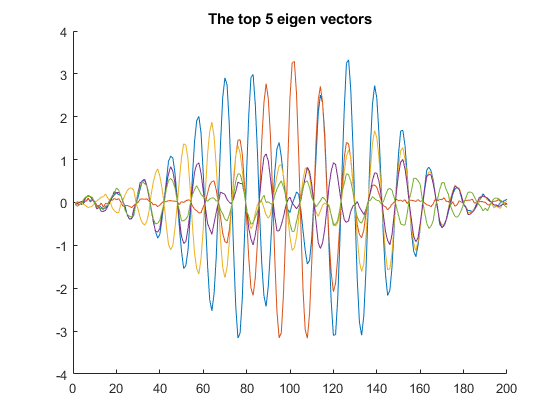

amplitudeNoise=10; % noise parameters
sigmaNoise=20;
t0Noise=20;
colouredNoise=0.3;

N=1000; % Number of signals to generate
X=zeros(n,N);

%% build up an 'observed' data set
for q=1:N
    A=5+amplitudeNoise*rand(1);  % The highest peak
    sigma=10+sigmaNoise*rand(1); % The "width" of pulse
    t0=100+t0Noise*randn(1);     % The center of the highest peak
    s=A*exp( -(t-t0).^2 / (2*sigma^2)).*cos(0.5*t);
    X(:,q)=s+step(dsp.ColoredNoise('InverseFrequencyPower', colouredNoise, 'SamplesPerFrame', n));
end

%% Calculate C using 14.206 and perform a KLT
C=zeros(n,n);
mean_vector = mean(X, 2); % Compute mean vector across all samples.
for q=1:N
    % x=X(:,q)-mean(X(:,q));  % Original code, seems wrong?
    x = X(:,q) - mean_vector; % My code
    C = C + x*x';
end
C=C/N;
[U, lambda, A]=svd(C);

%% Plot results
figure(1)
clf(figure(1))
hold on
for q=1:5
  plot(A(:,q)*sqrt(lambda(q,q)))
end
title('The top 5 eigen vectors')
hold off

figure(2)
stem(diag(lambda))
xlabel('Component')
ylabel('Eigenvalue')